dataset = readtable('/Users/lynnxt/Desktop/LOB_data.csv');
dataset

dataset = 621×5 table
    SourceTime    bid_price    bid_volume    ask_price    ask_volume
    __________    _________    __________    _________    __________

         1         134.36         100         135.36         100    
         2         149.34         100         150.34         100    
         3         141.75          80         142.75         100    
         4         141.75         106         142.75         100    
         5         141.58         100         142.58         100    
         6         142.07         100         143.07         100    
         7         119.02         100         120.02         100    
         8          130.1          10          131.1         100    
         9         134.62         100         135.62         100    
        10         136.67         100         137.67         100    
        11         139.39         100         140.39         100    
        12         140.11         100         141.11         100    
        13 

% Fake data

% calculate mid_price
dataset.mid_price = (dataset.ask_price + dataset.bid_price) / 2;

% midprice state
dataset.mid_price_status = repmat("keep", height(dataset), 1);

for i = 2:height(dataset)
    if dataset.mid_price(i) > dataset.mid_price(i-1)
        dataset.mid_price_status(i) = "up";
    elseif dataset.mid_price(i) < dataset.mid_price(i-1)
        dataset.mid_price_status(i) = "down";
    end
end
dataset

dataset = 621×7 table
    SourceTime    bid_price    bid_volume    ask_price    ask_volume    mid_price    mid_price_status
    __________    _________    __________    _________    __________    _________    ________________

         1         134.36         100         135.36         100         134.86           "keep"     
         2         149.34         100         150.34         100         149.84           "up"       
         3         141.75          80         142.75         100         142.25           "down"     
         4         141.75         106         142.75         100         142.25           "keep"     
         5         141.58         100         142.58         100         142.08           "down"     
         6         142.07         100         143.07         100         142.57           "up"       
         7         119.02         100         120.02         100         119.52           "down"     
         8          130.1          10          131.1       



% data splitting
cv = cvpartition(height(dataset), 'HoldOut', 0.2);

% train data
X_train = dataset(cv.training, :);
Y_train = X_train.mid_price_status;

% test data
X_test = dataset(cv.test, :);
Y_test = X_test.mid_price_status;

% Random Foreset
rfModel = TreeBagger(50, X_train(:, 1:end-1), Y_train, ...
    'Method', 'classification', 'OOBPredictorImportance', 'on');


[Y_pred, ~] = predict(rfModel, X_test(:, 1:end-1));


confMat = confusionmat(Y_test, Y_pred);


disp(confMat);

    48    25     3
    12    25     1
     5     3     2





accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 60.48%


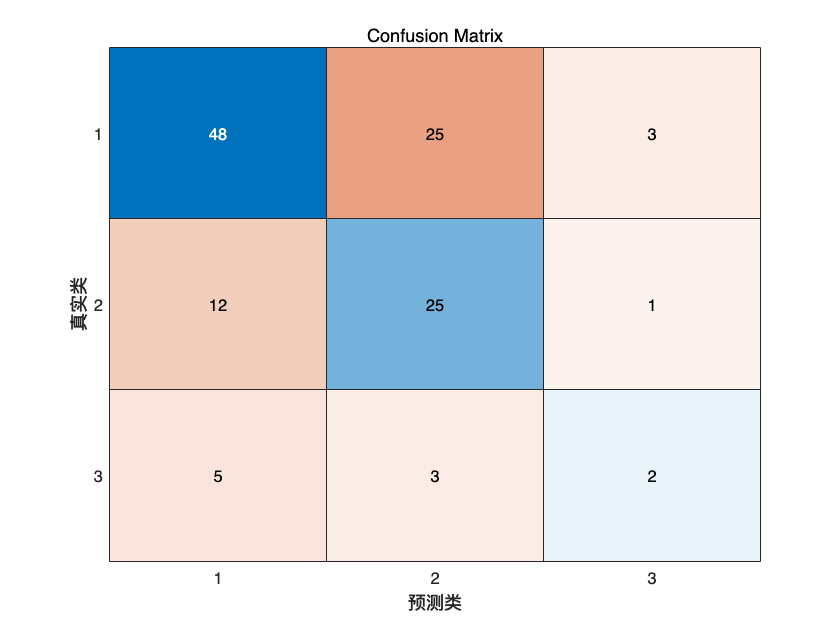


figure; 
confusionchart(confMat);
title('Confusion Matrix');

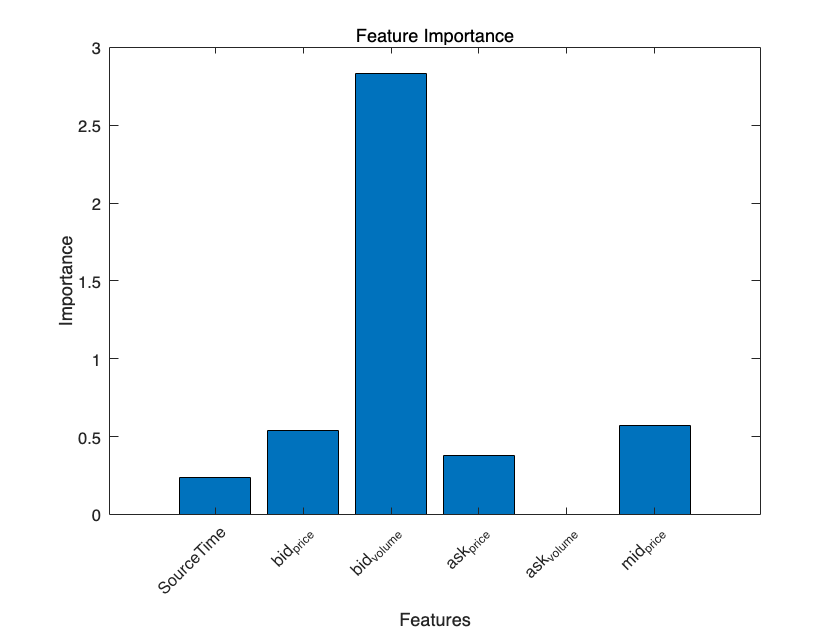



featureImportance = rfModel.OOBPermutedVarDeltaError;


figure; 
bar(featureImportance);
title('Feature Importance');
xlabel('Features');
ylabel('Importance');
set(gca, 'XTickLabel',dataset.Properties.VariableNames(1:end-1), 'XTick',1:numel(featureImportance))
xtickangle(45); 

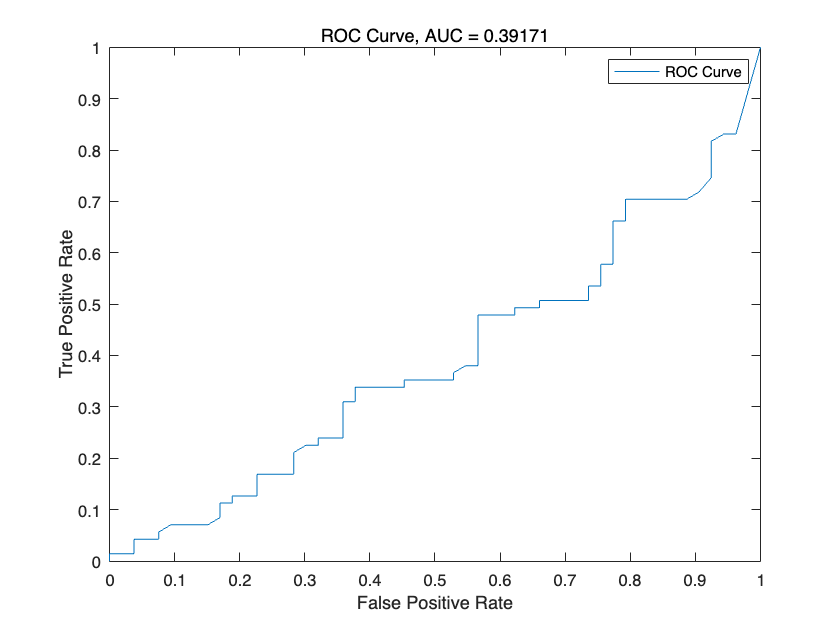



[Y_pred, scores] = predict(rfModel, X_test(:, 1:end-1));


[FPR, TPR, TH, AUC] = perfcurve(Y_test_logical, scores(:, 2), true);


figure;
plot(FPR, TPR);
legend('ROC Curve');
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curve, AUC = ' num2str(AUC)]);